% % MILP problem to risk appetite model
clc
clear all

% % Loading data set
IS = xlsread("Utility_estimation.xlsx",'IS_PA'); % Information System from respondent evaluations
Data_based_case = xlsread('Utility_estimation.xlsx','DT_PA'); % Utility estimation from RSGA


% % Define the features
U = Data_based_case(:,1); % Number of observation
Utility_R = round(Data_based_case(:,1:end-1)); % Number of utility estimation

Cond_R = IS(:,1:end-1); % Number of conditional seaport risk factors

Dec_R = Data_based_case(:,end); % Decisional seaport risk factor


% % Formulating the problem
utilityprob = optimproblem("ObjectiveSense","minimize")

utilityprob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.


e = optimvar('e',83,61,'Type','integer','LowerBound',0,'UpperBound',1);
show(e)

    [ e(1, 1)     e(1, 2)     e(1, 3)     e(1, 4)     e(1, 5)     e(1, 6)     e(1, 7)     e(1, 8)     e(1, 9)     e(1, 10)     e(1, 11)     e(1, 12)     e(1, 13)     e(1, 14)     e(1, 15)     e(1, 16)     e(1, 17)     e(1, 18)     e(1, 19)     e(1, 20)     e(1, 21)     e(1, 22)     e(1, 23)     e(1, 24)     e(1, 25)     e(1, 26)     e(1, 27)     e(1, 28)     e(1, 29)     e(1, 30)     e(1, 31)     e(1, 32)     e(1, 33)     e(1, 34)     e(1, 35)     e(1, 36)     e(1, 37)     e(1, 38)     e(1, 39)     e(1, 40)     e(1, 41)     e(1, 42)     e(1, 43)     e(1, 44)     e(1, 45)     e(1, 46)     e(1, 47)     e(1, 48)     e(1, 49)     e(1, 50)     e(1, 51)     e(1, 52)     e(1, 53)     e(1, 54)     e(1, 55)     e(1, 56)     e(1, 57)     e(1, 58)     e(1, 59)     e(1, 60)     e(1, 61)  ]
    [ e(2, 1)     e(2, 2)     e(2, 3)     e(2, 4)     e(2, 5)     e(2, 6)     e(2, 7)     e(2, 8)     e(2, 9)     e(2, 10)     e(2, 11)     e(2, 12)     e(2, 13)     e(2, 14)     e(2, 15)     e(2, 16)     e(2, 1

utilityEstimation = Utility_R;
riskPreferences = Cond_R;
Decisional_SR = Dec_R;
Percentage_utility = Utility_R.*Decisional_SR

Percentage_utility =            6           0          -8           2         -10           0           8         -14          14          -4           6          -4          -8         -10          12           8         -90         -86          52          54          80          98         -72         -78          44          12          12           4         -34          -4          12         -14           8           4           0         -28          -4          28         -48         -56         -34         116          58         -36         102         -48         -54         -30          14          16
          39          24         -28          74         -42         -11         -10         -24         -21        -108        -104          -1           0           2         119          93         -55         -55         -55          43         129          53          50         -55         -55          28         -47        -150         151          22         -45      

Freq_entities = length(Utility_R)/3

Freq_entities = 27.6667

F = 1./Freq_entities

F = 0.0361

pwra_utility = abs(Utility_R.^0.05)

pwra_utility =     1.0565         0    1.0718    1.0000    1.0838         0    1.0718    1.1022    1.1022    1.0353    1.0565    1.0353    1.0718    1.0838    1.0937    1.0718    1.2097    1.2069    1.1769    1.1791    1.2025    1.2148    1.1962    1.2010    1.1671    1.0937    1.0937    1.0353    1.1522    1.0353    1.0937    1.1022    1.0718    1.0353         0    1.1411    1.0353    1.1411    1.1722    1.1813    1.1522    1.2251    1.1834    1.1555    1.2172    1.1722    1.1791    1.1450    1.1022    1.1096
    1.2010    1.1722    1.1813    1.2401    1.2055    1.1274    1.1220    1.1722    1.1644    1.2638    1.2614    1.0000         0    1.0353    1.2699    1.2544    1.2219    1.2219    1.2219    1.2069    1.2751    1.2196    1.2160    1.2219    1.2219    1.1813    1.2123    1.2847    1.2851    1.1671    1.2097    1.2502    1.2123    1.2282    1.2292    1.2025    1.2025    1.2055    1.2219    1.3240    1.2219    1.2219    1.2219    1.2219    1.2349    1.1928    1.1928    1.2897    

predprob = pwra_utility/sum(pwra_utility(:))

predprob = 1.0e-03 *

    0.1854         0    0.1881    0.1755    0.1902         0    0.1881    0.1934    0.1934    0.1817    0.1854    0.1817    0.1881    0.1902    0.1919    0.1881    0.2123    0.2118    0.2065    0.2069    0.2110    0.2132    0.2099    0.2107    0.2048    0.1919    0.1919    0.1817    0.2022    0.1817    0.1919    0.1934    0.1881    0.1817         0    0.2002    0.1817    0.2002    0.2057    0.2073    0.2022    0.2150    0.2076    0.2027    0.2136    0.2057    0.2069    0.2009    0.1934    0.1947
    0.2107    0.2057    0.2073    0.2176    0.2115    0.1978    0.1969    0.2057    0.2043    0.2217    0.2213    0.1755         0    0.1817    0.2228    0.2201    0.2144    0.2144    0.2144    0.2118    0.2237    0.2140    0.2134    0.2144    0.2144    0.2073    0.2127    0.2254    0.2255    0.2048    0.2123    0.2194    0.2127    0.2155    0.2157    0.2110    0.2110    0.2115    0.2144    0.2323    0.2144    0.2144    0.2144    0.2144    0.2167    0.2093    0.2093    0.2

% % Creating expressions
Z = F.*sum(sum(Cond_R.*predprob.*utilityEstimation.*e))

Z =   Linear OptimizationExpression

    4.0202e-05*e(1, 1) + 0.0014853*e(2, 1) - 0.00046698*e(3, 1) + 0.0006766*e(4, 1) + 0.00014679*e(5, 1) + 0.00023313*e(6, 1) - 0.00069814*e(7, 1) - 2.7189e-05*e(8, 1) - 5.4379e-05*e(9, 1) - 0.00057375*e(10, 1) + 0.00075504*e(11, 1) + 0.0007003*e(12, 1) - 3.9395e-05*e(13, 1) - 0.00035685*e(14, 1) - 0.00013595*e(15, 1) + 0.00032569*e(16, 1) - 0.00099943*e(17, 1) + 9.7863e-05*e(18, 1) - 0.00061014*e(19, 1) - 0.00046687*e(20, 1) - 0.00048269*e(21, 1) - 0.00018746*e(22, 1) - 0.00034126*e(23, 1) + 0.0013297*e(24, 1) - 0.0001573*e(25, 1) + 0.0014746*e(26, 1) + 0.00051442*e(27, 1) - 0.00064221*e(28, 1) + 2.6263e-05*e(29, 1) - 0.00065655*e(30, 1) - 0.0011624*e(31, 1) + 0.00010131*e(32, 1) + 0.00057815*e(33, 1) + 0.00021785*e(34, 1) - 5.4379e-05*e(35, 1) + 0.0023953*e(36, 1) - 0.0011326*e(37, 1) - 0.00017843*e(38, 1) - 0.00075504*e(39, 1) - 0.00062616*e(40, 1) - 0

utilityprob.Objective = Z; % Objective function
show(Z)


  4.0202e-05*e(1, 1) + 0.0014853*e(2, 1)
- 0.00046698*e(3, 1) + 0.0006766*e(4, 1)
+ 0.00014679*e(5, 1) + 0.00023313*e(6, 1)
- 0.00069814*e(7, 1) - 2.7189e-05*e(8, 1)
- 5.4379e-05*e(9, 1) - 0.00057375*e(10, 1)
+ 0.00075504*e(11, 1) + 0.0007003*e(12, 1)
- 3.9395e-05*e(13, 1) - 0.00035685*e(14, 1)
- 0.00013595*e(15, 1) + 0.00032569*e(16, 1)
- 0.00099943*e(17, 1) + 9.7863e-05*e(18, 1)
- 0.00061014*e(19, 1) - 0.00046687*e(20, 1)
- 0.00048269*e(21, 1) - 0.00018746*e(22, 1)
- 0.00034126*e(23, 1) + 0.0013297*e(24, 1)
- 0.0001573*e(25, 1) + 0.0014746*e(26, 1)
+ 0.00051442*e(27, 1) - 0.00064221*e(28, 1)
+ 2.6263e-05*e(29, 1) - 0.00065655*e(30, 1)
- 0.0011624*e(31, 1) + 0.00010131*e(32, 1)
+ 0.00057815*e(33, 1) + 0.00021785*e(34, 1)
- 5.4379e-05*e(35, 1) + 0.0023953*e(36, 1)
- 0.0011326*e(37, 1) - 0.00017843*e(38, 1)
- 0.00075504*e(39, 1) - 0.00062616*e(40, 1)
- 0.0013131*e(41, 1) - 0.00018746*e(42, 1)
- 0.00013191*e(43, 1) - 0.00088498*e(44, 1)
- 4.8931e-05*e(45, 1) + 2.6263e-05*e(46, 1)
+ 2.62

% % Defining constaints
for m = 1:83
    for n = 1:61
        if utilityEstimation(m,n) ~= utilityEstimation(n)
            d_ikj(m,n) = 1;
        else
            d_ikj(m,n) = 0;
        end
    end
end

d_ikj_cons1 = sum(d_ikj.*e) <= 1

d_ikj_cons1 =   1×61 Linear OptimizationInequality array with properties:

    IndexNames: {{}  {}}
     Variables: [1×1 struct] containing 1 OptimizationVariable

  See inequality formulation with show.


utilityprob.Constraints.d_ikj_cons1 = d_ikj_cons1

utilityprob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 1 OptimizationConstraint

  See problem formulation with show.


% % Solve the problem
[sol, fval] = solve(utilityprob)

Solving problem using intlinprog.
LP:                Optimal objective value is -0.192245.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the
optimal value, options.AbsoluteGapTolerance = 0
(the default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the default
value).



sol = struct with fields:
    e: [83×61 double]


fval = -0.1922

sol.e

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

fval

fval = -0.1922

% % Plotting result
h = heatmap(sol.e)

h =   HeatmapChart with properties:

        XData: {61×1 cell}
        YData: {83×1 cell}
    ColorData: [83×61 double]

  Show all properties


h.Title = 'Risk appetite of Port Autorithy (Seaport-maneger and Seaport-operator) under Scenario III'

h =   HeatmapChart (Risk appetite of Port Autorithy (Seaport-maneger and Seaport-operator) under Scenario III) with properties:

        XData: {61×1 cell}
        YData: {83×1 cell}
    ColorData: [83×61 double]

  Show all properties


h.XLabel = 'Conditional seaport risk factors'

h =   HeatmapChart (Risk appetite of Port Autorithy (Seaport-maneger and Seaport-operator) under Scenario III) with properties:

        XData: {61×1 cell}
        YData: {83×1 cell}
    ColorData: [83×61 double]

  Show all properties


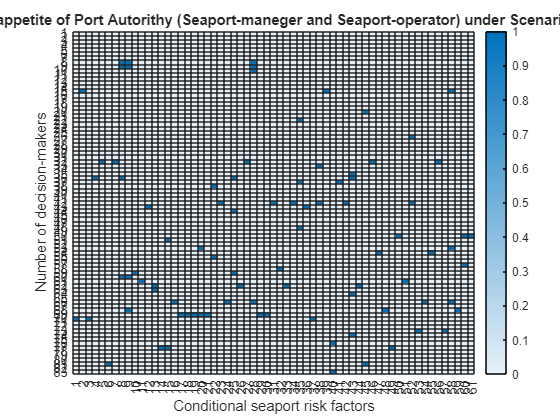

h =   HeatmapChart (Risk appetite of Port Autorithy (Seaport-maneger and Seaport-operator) under Scenario III) with properties:

        XData: {61×1 cell}
        YData: {83×1 cell}
    ColorData: [83×61 double]

  Show all properties


h.YLabel = 'Number of decision-makers'


s = surf(sol.e)

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [83×1 double]
           ZData: [83×61 double]
           CData: [83×61 double]

  Show all properties


s.EdgeColor = "interp"

s =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [83×1 double]
           ZData: [83×61 double]
           CData: [83×61 double]

  Show all properties


s.FaceColor = "interp"

s =   Surface with properties:

       EdgeColor: 'interp'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61]
           YData: [83×1 double]
           ZData: [83×61 double]
           CData: [83×61 double]

  Show all properties


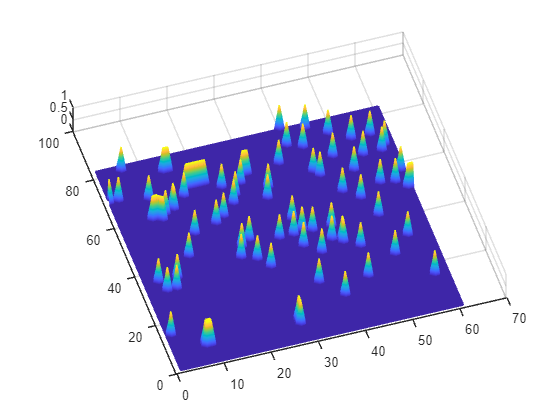

view([-17.489 84.623])